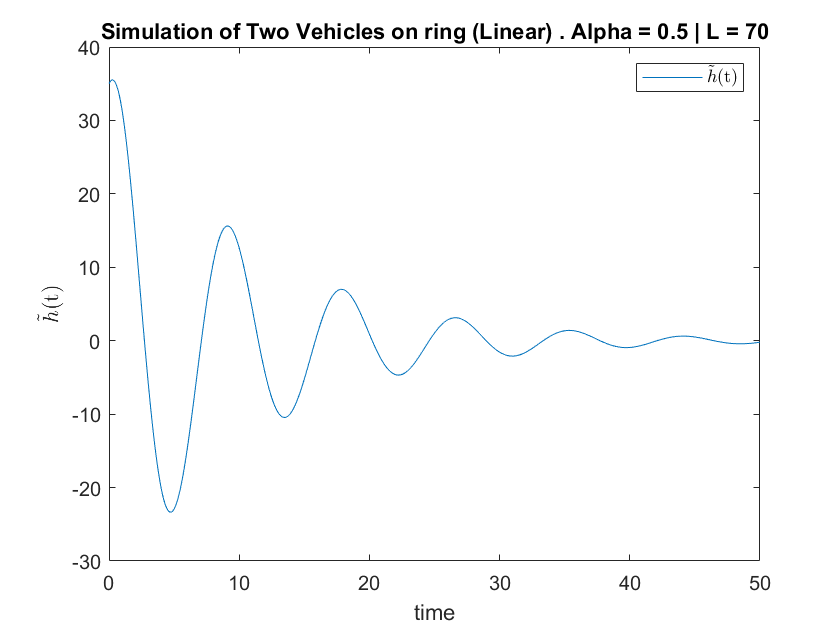

%HW3_Q3 Two Vehicle on the ring. (Linearizing about v* and h*)
clear all; close all;

%Parameters
tau = 0.8;
tstart = 0;
tdelta = 0.1;
tend = 50;
tspan = tstart:tdelta:tend;
vmax = 30;
hst = 5;
hgo = 45;


%Parameters selection after studying the stability chart.
alpha = 0.5;
L = 70;
kappa = vmax*(2*hgo - L)/(hgo - hst)^2;

%Initial Condition. Equivalent to y0 of ode45.
ic = @(t)[1 0 0];

%DDE setup
sol = dde23(@(t,y,ytau)ddefunc(t,y,ytau,alpha,kappa),tau,ic,tspan);
y = deval(sol,tspan);

%Plotting. (For linearized system, everything is in terms of perturbations)
figure(1);box on; hold on;
plot(tspan,y(1,:));
xlabel("time");
ylabel('$$\tilde{h}$$(t)', 'Interpreter', 'LaTeX');
title("Simulation of Two Vehicles on ring (Linear) . Alpha = "+alpha+" | L = "+L);
legend('$$\tilde{h}$$(t)', 'Interpreter', 'LaTeX');

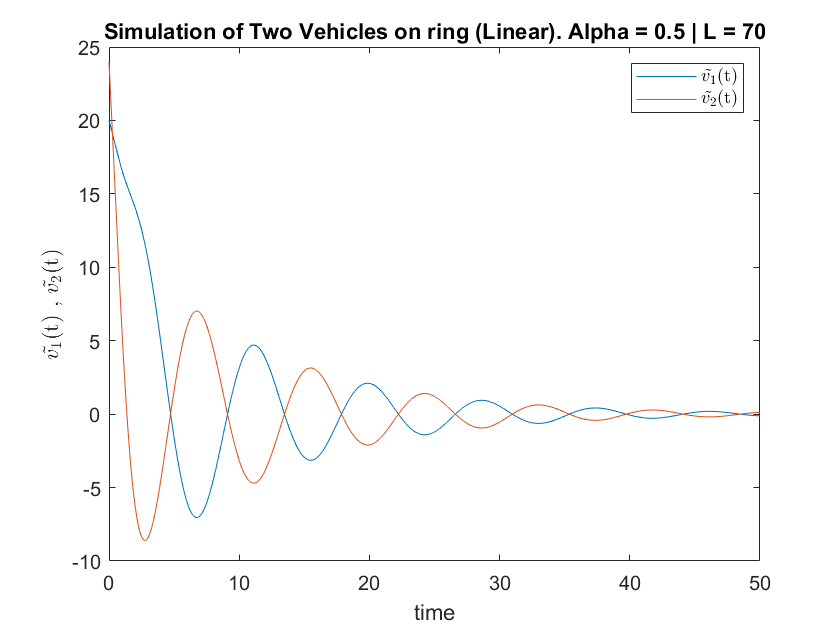



figure(2);box on; hold on;
plot(tspan,y(2,:));
plot(tspan,y(3,:));
xlabel("time");
ylabel('$$\tilde{v_1}$$(t) , $$\tilde{v_2}$$(t)', 'Interpreter', 'LaTeX');
title("Simulation of Two Vehicles on ring (Linear). Alpha = "+alpha+" | L = "+L);
legend('$$\tilde{v_1}$$(t)' , '$$\tilde{v_2}$$(t)','Interpreter', 'LaTeX');

function dydt = ddefunc(t,y,ytau,alpha,kappa)
    dydt(1) = y(3) - y(2);
    dydt(2) = alpha*kappa*ytau(1) - alpha*ytau(2);
    dydt(3) = -alpha*kappa*ytau(1) - alpha*ytau(3);
    
    dydt = dydt';
end
